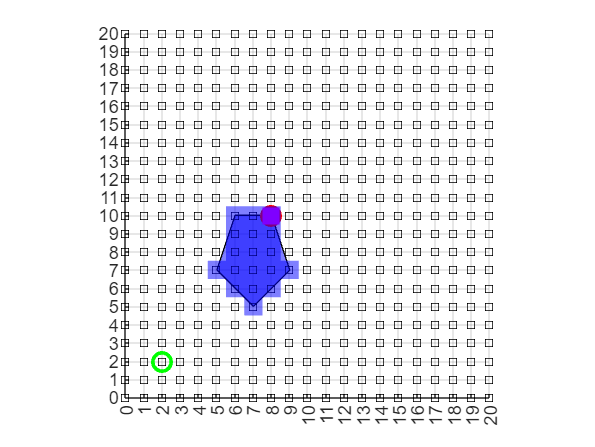

% Define the size of the grid
gridSize = 20;

% Create the figure and axes
figure;
hold on;
axis equal;
grid on;
set(gca, 'XTick', 0:gridSize, 'YTick', 0:gridSize); % Adjust grid size as needed
xlim([0 gridSize]);
ylim([0 gridSize]);

% Define the start point
start_point = [2, 2];

% Plot start point
plot(start_point(1), start_point(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);

% Define the object's vertices (pentagon)
object_vertices_x = [7, 9, 8, 6, 5];
object_vertices_y = [5, 7, 10, 10, 7];

% Create the object shape
fill(object_vertices_x, object_vertices_y, 'b', 'FaceAlpha', 0.5);

% Define grasp point on the object (let's use the top vertex for this example)
grasp_point = [8, 10];

% Plot final point (grasp point)
plot(grasp_point(1), grasp_point(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);

% Display grid
for i = 0:gridSize
    for j = 0:gridSize
        plot(i, j, 'ks', 'MarkerSize', 5, 'MarkerFaceColor', 'none');
    end
end

% Highlight the grasp point on the object
plot(grasp_point(1), grasp_point(2), 'ms', 'MarkerSize', 10, 'LineWidth', 2, 'MarkerFaceColor', 'magenta');

% Create a polygon from the object's vertices
[xq, yq] = meshgrid(0:gridSize, 0:gridSize);
in = inpolygon(xq, yq, object_vertices_x, object_vertices_y);

% Create matrix A representing the 2D space
A = inf(gridSize + 1, gridSize + 1); % Initialize with inf values

% Mark the start point in A (transposed)
A(gridSize - start_point(2) + 1, start_point(1) + 1) = 0; % Starting point set to 0

% Highlight the cells inside the polygon and update the matrix A (transposed)
for i = 1:numel(xq)
    if in(i)
        A(gridSize - yq(i) + 1, xq(i) + 1) = -1; % Using -1 to represent the object
        fill(xq(i) + [-0.5 0.5 0.5 -0.5], yq(i) + [-0.5 -0.5 0.5 0.5], 'b', 'FaceAlpha', 0.5, 'EdgeColor', 'none');
    end
end

% Mark the grasp point in A (transposed)
A(gridSize - grasp_point(2) + 1, grasp_point(1) + 1) = -2;
    
hold off;


% Print the matrix A to the screen
disp('Matrix A:');

Matrix A:


disp(A);

   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   


% Display the final point (grasp point) in the matrix A
final_point_value = A(gridSize - grasp_point(2) + 1, grasp_point(1) + 1);
disp(['Final point (grasp point) value in A: ', num2str(final_point_value)]);

Final point (grasp point) value in A: -2
